Find $c_1 \; c_2 \; c_3 \ni$


$$p(1) = c_1+c_2+c_3 = 1.1$$



$$p(2) = c_1 + 2 c_2 + 2^2  c_3 = 1.3$$



$$p_2(3) = c_1 + 3 c_2 +   3^3 c_3 = 1.4$$



$$p(x) = c_1 + c_2 x + c_3 x^2$$


V = [1 1 1; 1 2 4;1 3 9];
y = [1.1 1.3 1.4]';
c_poly = V \ y

c_poly =     0.8000
    0.3500
   -0.0500


Check

c_poly(1) + 1 * c_poly(2) + 1 *c_poly(3) 

ans = 1.1000

c_poly(1) + 2 * c_poly(2) + 4 *c_poly(3) 

ans = 1.3000

c_poly(1) + 3 * c_poly(2) + 9 *c_poly(3) 

ans = 1.4000

OK!

Now let $p(x) = c_1 + c_2 e^x + c_3 e^{-x}$ and find the interpolant. 

V = [ 1 exp(1) exp(-1); 1 exp(2) exp(-2) ; 1 exp(3) exp(-3)];
y= [1.1 1.3 1.4]';
c_exp=V\ y

c_exp =     1.3921
    0.0024
   -0.8117


Check

c_exp(1) + exp(1) * c_exp(2) + exp(-1) *c_exp(3) 

ans = 1.1000

c_exp(1) + exp(2) * c_exp(2) + exp(-2) *c_exp(3) 

ans = 1.3000

c_exp(1) + exp(3) * c_exp(2) + exp(-3) *c_exp(3) 

ans = 1.4000

OK!

Let's plot

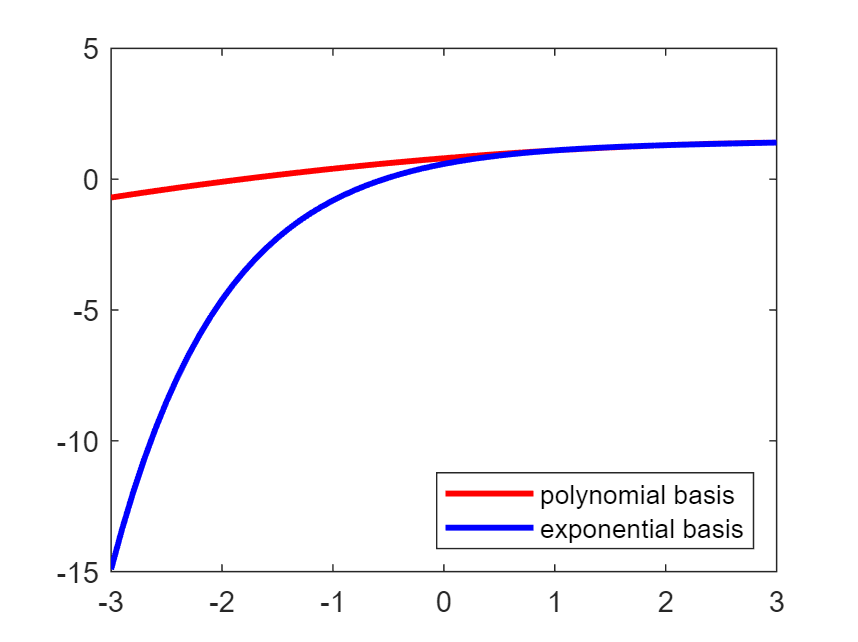

x = -3 : .1 : 3;
%x= [1 2 3]
f1 = c_poly(1) + x * c_poly(2) +  x.^2 * c_poly(3);
f2 = c_exp(1) + exp(x) * c_exp(2) + exp(-x) * c_exp(3);

figure(1)
plot(x,f1,"r-","Linewidth",2);
hold on;
plot(x,f2,"b-","Linewidth",2);
legend('polynomial basis','exponential basis','Location','southeast')